# Impedance Matching Problem using Chebyshev Polynomials

clear; clc; close all;


% Estimation of Chebyshev Polynomials: Given
syms Theta
Coeff_Chebyshev        = { [sec(Theta)] ,...
                           [sec(Theta)^2-1,sec(Theta)^2  ] ,...
                           [3*sec(Theta)^3-3*sec(Theta),sec(Theta)^3  ] ,...
                           [3*sec(Theta)^4-4*sec(Theta)^2+1 ,4*sec(Theta)^4-4*sec(Theta)^2 , sec(Theta)^4]};


N = 3;
A = 0.05; % Given
ZL = 100; Z0= 50; % Given

% From 5-61 we Have:
Sec_m = cosh( 1/N*acosh(  ( log(ZL/Z0)/(2*A) )  ));
Theta_m = asec(Sec_m)*180/pi;
Gamma_Approx_N = Coeff_Chebyshev{N};
Gamma_Weights  = zeros(size(Gamma_Approx_N)); 
for i=1:length(Gamma_Approx_N)
    Temp(Theta) = Gamma_Approx_N(i);
    Gamma_Weights(1,i) = A*double(Temp(Theta_m*pi/180))/(2);
end

% Symmetry:
Gamma_Total_N = [ flip(Gamma_Weights) , Gamma_Weights ];
disp("Theta_m = "+Theta_m)

Theta_m = 44.7273


disp("Gamma Values are: ")

Gamma Values are: 


disp(Gamma_Total_N)

    0.0697    0.1036    0.1036    0.0697



## Now Calculation of Intrinsic Impedances:


Z = zeros(1,length(Gamma_Total_N)-1);
Z(1,1) = Z0;

for i=2:length(Gamma_Total_N)
    Z(1,i) = exp(log(Z(1,i-1))+2*Gamma_Total_N(i-1));
end
disp("Intrinsic Impedances are: ")

Intrinsic Impedances are: 


disp(Z)

   50.0000   57.4807   70.7107   86.9858



Delta_f_vs_f0 = 2 - 4*Theta_m/180

Delta_f_vs_f0 = 1.0061

## For N = 2

N = 2;
Sec_m = cosh( 1/N*acosh(  ( log(ZL/Z0)/(2*A) )  ));
Theta_m = asec(Sec_m)*180/pi;
Gamma_Approx_N = Coeff_Chebyshev{N};
Gamma_Weights  = zeros(size(Gamma_Approx_N)); 
for i=1:length(Gamma_Approx_N)
    Temp(Theta) = Gamma_Approx_N(i);
    Gamma_Weights(1,i) = A*double(Temp(Theta_m*pi/180))/(2);
end

% Symmetry:
Gamma_Total_N = [ flip(Gamma_Weights) , Gamma_Weights ];
disp("Theta_m = "+Theta_m)

Theta_m = 59.8573


disp("Gamma Values are: ")

Gamma Values are: 


disp(Gamma_Total_N)

    0.0991    0.0741    0.0741    0.0991




Z = zeros(1,length(Gamma_Total_N)-1);
Z(1,1) = Z0;

for i=2:length(Gamma_Total_N)
    Z(1,i) = exp(log(Z(1,i-1))+2*Gamma_Total_N(i-1));
end
disp("Intrinsic Impedances are: ")

Intrinsic Impedances are: 


disp(Z)

   50.0000   60.9656   70.7107   82.0135



Delta_f_vs_f0 = 2 - 4*Theta_m/180

Delta_f_vs_f0 = 0.6698

## For N = 1

N = 1;
Sec_m = cosh( 1/N*acosh(  ( log(ZL/Z0)/(2*A) )  ));
Theta_m1 = asec(Sec_m)*180/pi;
Gamma_Approx_N = Coeff_Chebyshev{N};
Gamma_Weights  = zeros(size(Gamma_Approx_N)); 
for i=1:length(Gamma_Approx_N)
    Temp(Theta) = Gamma_Approx_N(i);
    Gamma_Weights(1,i) = A*double(Temp(Theta_m1*pi/180))/(2);
end

% Symmetry:
Gamma_Total_N1 = [ flip(Gamma_Weights) , Gamma_Weights ];
disp("Theta_m = "+Theta_m_N1)

Theta_m = 81.705


disp("Gamma Values are: ")

Gamma Values are: 


disp(Gamma_Total_N1)

    0.1733    0.1733




Z_N1 = zeros(1,length(Gamma_Total_N1)-1);
Z_N1(1,1) = Z0;

for i=2:length(Gamma_Total_N1)
    Z_N1(1,i) = exp(log(Z_N1(1,i-1))+2*Gamma_Total_N1(i-1));
end
disp("Intrinsic Impedances are: ")

Intrinsic Impedances are: 


disp(Z_N1)

   50.0000   70.7107



Delta_f_vs_f0_N1 = 2 - 4*Theta_m1/180

Delta_f_vs_f0 = 0.1843

## For N = 4

N = 4;
Sec_m = cosh( 1/N*acosh(  ( log(ZL/Z0)/(2*A) )  ));
Theta_m4 = asec(Sec_m)*180/pi;
Gamma_Approx_N = Coeff_Chebyshev{N};
Gamma_Weights  = zeros(size(Gamma_Approx_N)); 
for i=1:length(Gamma_Approx_N)
    Temp(Theta) = Gamma_Approx_N(i);
    Gamma_Weights(1,i) = A*double(Temp(Theta_m4*pi/180))/(2);
end

% Symmetry:
Gamma_Total_N4 = [ flip(Gamma_Weights) , Gamma_Weights ];
disp("Theta_m = "+Theta_m4)

Theta_m = 35.148


disp("Gamma Values are: ")

Gamma Values are: 


disp(Gamma_Total_N4)

    0.0559    0.0741    0.0432    0.0432    0.0741    0.0559




Z_N4 = zeros(1,length(Gamma_Total_N4)-1);
Z_N4(1,1) = Z0;

for i=2:length(Gamma_Total_N4)
    Z_N4(1,i) = exp(log(Z_N4(1,i-1))+2*Gamma_Total_N4(i-1));
end
disp("Intrinsic Impedances are: ")

Intrinsic Impedances are: 


disp(Z_N4)

   50.0000   55.9177   64.8558   70.7107   77.0941   89.4172



Delta_f_vs_f0_N4 = 2 - 4*Theta_m4/180

Delta_f_vs_f0_N4 = 1.2189

## Frequency Plot of abs(Gamma):

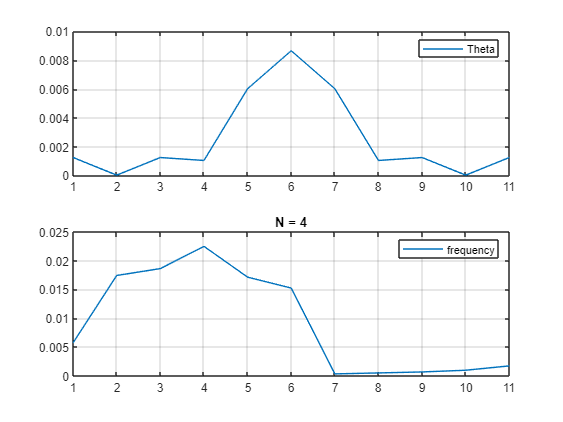

theta_vec = -pi/2:pi/10:pi/2;

N = 4;
Gamma_theta_N4 = A*exp(-1j*N*theta_vec).*(Gamma_Total_N4(1:floor(length(Gamma_Total_N4)/2))*cos((N:-2:0)'*theta_vec));
figure()
subplot(2,1,1)
plot(abs(Gamma_theta_N4))
grid on
legend("Theta")
title("N = "+N)
subplot(2,1,2)
plot(abs(   fftshift(fft(Gamma_theta_N4))  ));
legend("frequency")
grid on


## Putting it All Together in a Function:

Theta_m = 44.7273
Gamma Values are: 
    0.0697    0.1036    0.1036    0.0697

Intrinsic Impedances are: 
   50.0000   57.4807   70.7107   86.9858



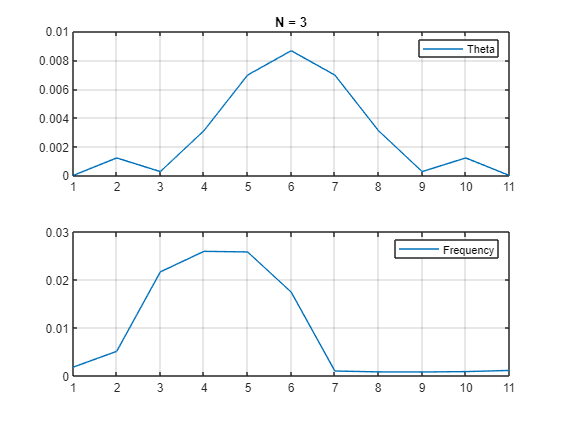

Model_Cheb = struct with fields:
    Gamma_Total_N: [5.9371e-35 + 3.2320e-19i 9.8671e-04 + 7.1689e-04i 2.5782e-04 - 8.3770e-05i -0.0010 + 0.0030i 0.0041 + 0.0056i 0.0087 + 0.0000i 0.0041 - 0.0056i -0.0010 - 0.0030i 2.5782e-04 + 8.3770e-05i 9.8671e-04 - 7.1689e-04i … ]
    Delta_f_vs_f0: 1.0061
          Theta_m: 44.7273


% For N=3:
N = 3; ZL = 100; Z0 = 50;
Model_Cheb = chebyshev_designer_Match(N,Coeff_Chebyshev,ZL,Z0,A)

## Functions:

function Model_Cheb = chebyshev_designer_Match(N,Coeff,ZL,Z0,A)
syms Theta

% From 5-61 we Have:
Sec_m = cosh( 1/N*acosh(  ( log(ZL/Z0)/(2*A) )  ));
Theta_m = asec(Sec_m)*180/pi;
Gamma_Approx_N = Coeff{N};
Gamma_Weights  = zeros(size(Gamma_Approx_N)); 
for i=1:length(Gamma_Approx_N)
    Temp(Theta) = Gamma_Approx_N(i);
    Gamma_Weights(1,i) = A*double(Temp(Theta_m*pi/180))/(2);
end

% Symmetry:
Gamma_Total_N = [ flip(Gamma_Weights) , Gamma_Weights ];
disp("Theta_m = "+Theta_m)
disp("Gamma Values are: ")
disp(Gamma_Total_N)

Z = zeros(1,length(Gamma_Total_N)-1);
Z(1,1) = Z0;

for i=2:length(Gamma_Total_N)
    Z(1,i) = exp(log(Z(1,i-1))+2*Gamma_Total_N(i-1));
end
disp("Intrinsic Impedances are: ")
disp(Z)
Delta_f_vs_f0 = 2 - 4*Theta_m/180;


theta_vec = -pi/2:pi/10:pi/2;


Gamma_Total_N = A*exp(-1j*N*theta_vec).*(Gamma_Total_N(1:floor(length(Gamma_Total_N)/2))*cos((N:-2:0)'*theta_vec));
figure()
subplot(2,1,1)
plot(abs(Gamma_Total_N))
grid on
legend("Theta")
title("N = "+N)
subplot(2,1,2)
plot(abs(   fftshift(fft(Gamma_Total_N))  ));
legend("Frequency")
grid on


Model_Cheb.Gamma_Total_N = Gamma_Total_N;
Model_Cheb.Delta_f_vs_f0 = Delta_f_vs_f0;
Model_Cheb.Theta_m = Theta_m;
end


